# **Movimento Quadrato Smussato**

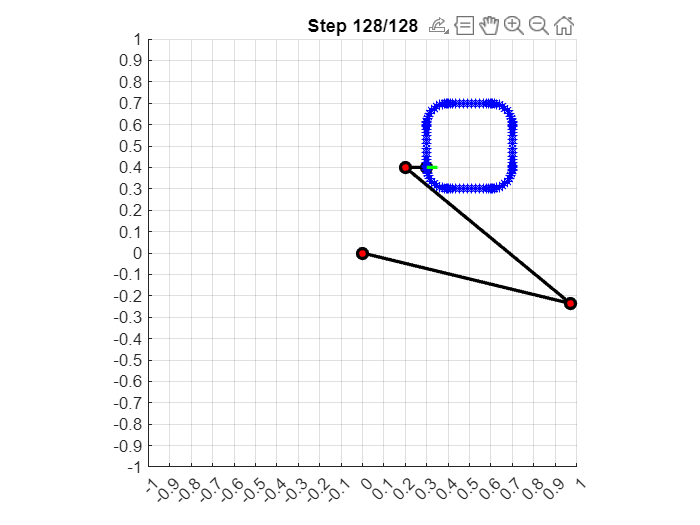

%funzione di cinematica inversa è la stessa
function [angoli] = cinematica_inversa(l1,l2,l3,px, py, angolo)
    
    %funzione che implementa la cinematica inversa dove
    %l1, l2, l3 sono le lunghezze dei tre bracci e
    %px e py le coordinate del punto in cui si vuole portare il robot
    %restituisce un vetore di angoli, corrispondenti alle variabili di 
    %giunto q1, q2, q3

    
    %dal momento che il vettore degli angoli ci restituisce q1,q2 e q3
    %è importante specificare che per come è sto definito il problema 

    %la prima cosa che si deve andare a fare è capire se il sistema 
    %ammette soluzioni, dunque se il punto che abbiamo come destinazione
    %è all'interno dello spazio su cui andiamo a lavorare
    if sqrt(px^2+py^2) > (l1+l2+l3)
        disp("il punto (py,px) è fuori dal range di lavoro")
        return
    end

    if l2<l1 && (sqrt(px^2+py^2) < (l1-l2))
        disp("il punto (py,px) è fuori dal range di lavoro")
        return
    end

    %2) Inizialize the system of equation
    c2=(px^2+py^2-l2^2-l1^2)/(2*l1*l2);
    %c2 = max(min(c2, 1), -1); % Limita c2 all'intervallo [-1, 1]
    s2=sqrt(1-c2^2); % in verità qui si potrebbe usare anche =-sqrt(1-c2^2)
    %questo dipende se si preferisce una soluzione a gomito alto o a gomito
    %basso

    c1s1=(1/(l1^2+l2^2+2*l1*l2*c2))*[l1+l1*c2 , l2*s2; -l2*s2, l1+l2*c2]*[px;py];
    
    c1= c1s1(1:1);
    s1=c1s1(2:2);

    q1=atan2(s1,c1);
    q2=atan2(s2,c2);
    


    q3 = angolo - q1 - q2;

    angoli=[q1,q2,q3];

end



function [angoli, vel, tempo] = movimenti(P1, P2, l1, l2, l3, verso)
    %istanzio i tempi 
    t_inizio = 0; 
    stepTime = 0.1;  
    t_fine = 1.5;
    tempo = t_inizio:stepTime:t_fine; 
    durata = t_fine - t_inizio;
    %normalizzo il tempo 
    tau = (tempo - t_inizio) / durata;
    %implemento la legge oraria
    lambda = 3*tau.^2 - 2*tau.^3;

    angoli = zeros(length(lambda), 3);
    vel = zeros(length(lambda), 3);

    %mi calcolo con la funzione di cinematica inversa le configurazioni dei
    %giunti 
    for i = 1:length(lambda)
        %parametrizzazione del segmento 
        p = P1 + lambda(i)*(P2 - P1);
        angoli(i,:) = cinematica_inversa(l1, l2, l3, p(1), p(2), verso);
    end
    
    %istanzio la derivata che mi servirà poi per la velocità 
    dq_dt = zeros(size(angoli));
   
    for i = 2:length(angoli)-1
        dq_dt(i,:) = (angoli(i+1,:) - angoli(i-1,:)) / (2*stepTime);
    end
    
    dq_dt(1,:) = 0;
    dq_dt(end,:) = 0;

    for i = 1:length(lambda)
        %per una questione di leggibilità 
        q1 = angoli(i,1); q2 = angoli(i,2); q3 = angoli(i,3);
        %preparo la jacobiana
        J = [ l1*sin(q1) - l2*sin(q1+q2) - l3*sin(q1+q2+q3), -l2*sin(q1+q2) - l3*sin(q1+q2+q3), -l3*sin(q1+q2+q3);
              l1*cos(q1) + l2*cos(q1+q2) + l3*cos(q1+q2+q3),  l2*cos(q1+q2) + l3*cos(q1+q2+q3),  l3*cos(q1+q2+q3);
              0, 0, 0; 
              0, 0, 0;
              0, 0, 0;
              1, 1, 1 ];
        v_cartesiane = J * dq_dt(i,:)';
        %ottengo le velocità 
        vel(i,:) = [v_cartesiane(1:2)' v_cartesiane(6)];
    end
end


function [angoli, vel, tempo] = movimenti_roto(centro_x, centro_y, raggio, vecchio_or, nuovo_or, l1, l2, l3)

    t_inizio = 0;
    stepTime = 0.1;
    t_fine = 1.5;
    tempo = t_inizio : stepTime : t_fine;
    durata = t_fine - t_inizio;

    tau = (tempo - t_inizio) / durata;
    lambda = 3 * tau.^2 - 2 * tau.^3;

    angoli = zeros(length(lambda), 3);
    vel = zeros(length(lambda), 3);

    for i = 1:length(lambda)
        orientamento = vecchio_or - (vecchio_or - nuovo_or) * lambda(i);
        px = centro_x - (raggio + l3) * cos(orientamento);
        py = centro_y - (raggio + l3) * sin(orientamento);
        angoli(i,:) = cinematica_inversa(l1, l2, l3, px, py, orientamento);
    end

    dq_dt = zeros(size(angoli));
    for i = 2:length(angoli)-1
        dq_dt(i,:) = (angoli(i+1,:) - angoli(i-1,:)) / (2 * stepTime);
    end
    %forzo le derivate
    dq_dt(1,:) = 0;
    dq_dt(end,:) = 0;

    for i = 1:length(lambda)
        q1 = angoli(i,1);
        q2 = angoli(i,2);
        q3 = angoli(i,3);

        J = [
             l1*sin(q1) + l2*sin(q1+q2) + l3*sin(q1+q2+q3),   l2*sin(q1+q2) + l3*sin(q1+q2+q3),   l3*sin(q1+q2+q3);
            -l1*cos(q1) - l2*cos(q1+q2) - l3*cos(q1+q2+q3),  -l2*cos(q1+q2) - l3*cos(q1+q2+q3),  -l3*cos(q1+q2+q3);
             0, 0, 1
        ];

        vel(i,:) = J * dq_dt(i,:)';
    end
end


%mettiamo i nostri dati 
l1 = 1;
l2 = 1;
l3 = 0.1;
%definisco i punti
P0 = [0.2,0.4];
P1 = [0.2,0.6];

[angoli,vel,tempo] = movimenti(P0,P1,l1,l2,l3,0);

c1_x = 0.4;
c1_y = 0.6;

[angoli_rot1,vel_rot1,tempo_rot1] = movimenti_roto(c1_x,c1_y,l3,0,-pi/2,l1,l2,l3);

P2 = [0.4,0.8]; 
P3 = [0.6,0.8];

[angoli2,vel2,tempo2] = movimenti(P2, P3, l1,l2,l3,-pi/2);

c2_x = 0.6;
c2_y = 0.6;

[angoli_rot2,vel_rot2,tempo_rot2] = movimenti_roto(c2_x,c2_y,l3,-pi/2,-pi,l1,l2,l3);

P4 = [0.8,0.6];
P5 = [0.8,0.4];
[angoli3,vel3,tempo3] = movimenti(P4, P5, l1,l2,l3,pi);
c3_x = 0.6;
c3_y = 0.4;

[angoli_rot3, vel_rot3,tempo_rot3] = movimenti_roto(c3_x, c3_y, l3, -pi, -(3*pi)/2,l1,l2,l3 );

P6 = [0.6,0.2];
P7 = [0.4,0.2];

[angoli4, vel4,tempo4] = movimenti(P6,P7,l1,l2,l3,pi/2);

c4_x = 0.4;
c4_y = 0.4;

[angoli_rot4, vel_rot4, tempo_rot4] = movimenti_roto(c4_x, c4_y, l3, -(3*pi)/2, -2*pi,l1,l2,l3 );

%funzione di animazione che rimane la stessa
%funzione per animare il robot 

function animazione_robot_planare(angoli, l1, l2, l3)
    % angoli: matrice n x 3 dove ogni riga è [theta1, theta2, theta3]

    figure;
    axis equal;
    axis([-1 1 -1 1]); % adatta in base alla tua workspace
    xticks(-1:0.1:1);
    yticks(-1:0.1:1);
    grid on;
    hold on;

    % Colori
    colore_braccio = 'k';
    colore_giunti = 'ro';
    colore_traiettoria = 'b*';
    colore_orientamento = 'g';

    % Per salvare la traiettoria dell’end-effector
    traiettoria_x = [];
    traiettoria_y = [];

    for i = 1:size(angoli,1)
        q = angoli(i,:);

        % Cinematica diretta per trovare i punti dei giunti
        theta1 = q(1); theta2 = q(2); theta3 = q(3);

        x1 = l1 * cos(theta1);
        y1 = l1 * sin(theta1);

        x2 = x1 + l2 * cos(theta1 + theta2);
        y2 = y1 + l2 * sin(theta1 + theta2);

        x3 = x2 + l3 * cos(theta1 + theta2 + theta3);
        y3 = y2 + l3 * sin(theta1 + theta2 + theta3);

        % Memorizza traiettoria
        traiettoria_x(end+1) = x3;
        traiettoria_y(end+1) = y3;

        % Cancella frame precedente
        cla;

        % Disegna i link
        plot([0 x1 x2 x3], [0 y1 y2 y3], 'o-', 'Color', colore_braccio, ...
            'MarkerFaceColor', 'r', 'LineWidth', 2);

        % Disegna traiettoria dell’end-effector
        plot(traiettoria_x, traiettoria_y, colore_traiettoria);

        % Disegna orientamento end-effector (come "pettinino")
        % Un piccolo segmento centrato in (x3, y3), orientato come q1+q2+q3
        phi = theta1 + theta2 + theta3;
        lunghezza_pettine = 0.05;  % piccola lunghezza
        xp = [x3, x3 + lunghezza_pettine * cos(phi)];
        yp = [y3, y3 + lunghezza_pettine * sin(phi)];
        plot(xp, yp, '-', 'Color', colore_orientamento, 'LineWidth', 2);

        % Titolo
        title(sprintf('Step %d/%d', i, size(angoli,1)));
        pause(0.15);
    end
end

function grafico_vel(vel, tempo)
    figure;
    subplot(2,1,1);
    plot(tempo, vel(:,1), 'r', 'LineWidth', 1.5); hold on;
    plot(tempo, vel(:,2), 'b', 'LineWidth', 1.5);
    ylabel('Velocità lineari [m/s]');
    legend('v_x','v_y'); grid on;
    title('Velocità lineari dell''end-effector');

    subplot(2,1,2);
    plot(tempo, vel(:,3), 'k', 'LineWidth', 1.5);
    ylabel('\omega_z [rad/s]');
    xlabel('Tempo [s]');
    title('Velocità angolare dell''end-effector');
    grid on;
end

tempo_rot1 = tempo_rot2 + tempo(end) + 0.1; 
tempo2 = tempo2 + tempo_rot1(end) + 0.1; 
tempo_rot2 = tempo_rot2 + tempo2(end) + 0.1;
tempo3 = tempo3 + tempo_rot2(end) + 0.1; 
tempo_rot3 = tempo_rot3 + tempo3(end) + 0.1;
tempo4 = tempo4 + tempo_rot3(end) + 0.1;
tempo_rot4 = tempo_rot4 + tempo4(end) + 0.1;

tempo_tot = [tempo, tempo_rot1, tempo2, tempo_rot2, tempo3, tempo_rot3, tempo4, tempo_rot4];
angoli_tot = [angoli;angoli_rot1;angoli2;angoli_rot2;angoli3;angoli_rot3;angoli4;angoli_rot4];

vel_tot = [vel;vel_rot1;vel2;vel_rot2;vel3;vel_rot3;vel4;vel_rot4];
animazione_robot_planare(angoli_tot,l1,l2,l3)

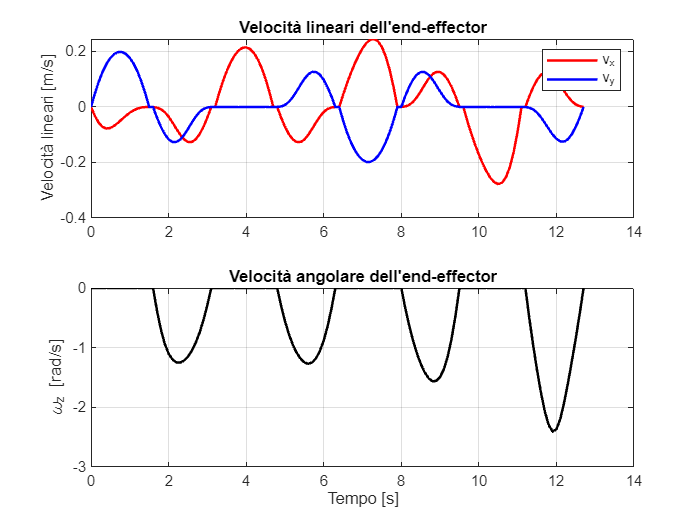

grafico_vel(vel_tot,tempo_tot)